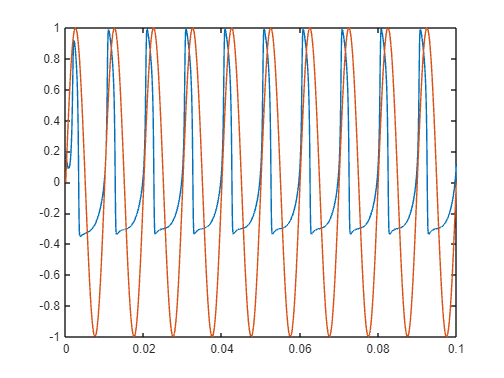

params.Tau = 2100.00;
params.TauR = 1500.00;
params.gc = 9.00;
params.NaX = 0.70;
params.alpha = 8.00;
params.b = 1.00;

% Parameter adjustments for single neuron simulation (without dendritic tree)
paramsSingleNeuron = params;
paramsSingleNeuron.NaX = 1; % Always 1

% Initial conditions
initCon = [0.2; 0.2];

% Initialze tree model
tree = DendriteTreeModel();

% Initalize soma & dendrites
soma = Dendrite(0, paramsSingleNeuron, initCon);             
dendrite = Dendrite(0, params, initCon);                     

% Add soma to tree
tree.addDendrite(soma);

% Add 2 similar dendrites, incrementing their ids
for i=1:2                                                    
    dendrite.ID = i;                                         
    tree.addDendrite(dendrite);
end                                                          

% Define connections
% Here dendrites will be parallel to soma
tree.addConnectionStr("0-[1,2]"); 

% Optional - verify tree integrity, method will throw out na error with
% detailed description if tree's integrity is broken
tree.verify();

% Initilize simulation parametrs
tmax = 0.1;
h = 1e-5;

% Generate stimuli signal
t = 0:h:tmax;
sig = sin(2*pi*100*t);

% Assign stimuli to dendrites with ids 1 & 2
tree.addStimuli(1, sig);
tree.addStimuli(2, sig);

% Solve with custom mex solver
[~, sol] = RK4CPP(tree, tmax, h);

% plot soma response agins stimuli signal
figure
plot(t, [sol(1, :); sig])